clear;

syms t theta(t)
syms m l g J c

q = [theta(t)];
dq = diff(q(1),t);
ddq = diff(dq(1), t);

x = l*sin(q(1));
y = l*cos(q(1));

dx = diff(x,q(1))*dq(1);
dy = diff(y,q(1))*dq(1);


% 並進
Kt = 1/2 * m * (dx^2 + dy^2);

% 位置
U = m * g * (l-y);

% 損失
D = (1/2) * c * dq(1)^2

$$D = \frac{c\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$


% ラグラジアン
L = Kt - U;

% 運動方程式

dLq = diff(L, dq(1));

ddLq = diff(dLq, dq(1))*ddq(1) + diff(dLq, q(1))*dq(1);

eq = ddLq - diff(L, q(1)) + diff(D, dq(1)) == 0

$$eq = \frac{m\,\left(2\,l^{2}\,{\cos\left(\theta \left(t\right)\right)}^{2}+2\,l^{2}\,{\sin\left(\theta \left(t\right)\right)}^{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)}{2}+c\,\frac{\partial }{\partial t}\theta \left(t\right)+g\,l\,m\,\sin\left(\theta \left(t\right)\right)=0$$



% syms t theta(t)
% syms m l g J c

m = 5;
l = 1;
g = 9.81;
c = 2;

eqn = subs(eq)

$$eqn = \frac{5\,\left(2\,{\cos\left(\theta \left(t\right)\right)}^{2}+2\,{\sin\left(\theta \left(t\right)\right)}^{2}\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)}{2}+2\,\frac{\partial }{\partial t}\theta \left(t\right)+\frac{981\,\sin\left(\theta \left(t\right)\right)}{20}=0$$

[V, State] = odeToVectorField(eqn)

$$V = \left(\begin{array}{c} Y_{2}\\ -\frac{981\,\sin\left(Y_{1}\right)+40\,Y_{2}}{100\,\left({\cos\left(Y_{1}\right)}^{2}+{\sin\left(Y_{1}\right)}^{2}\right)} \end{array}\right)$$

$$State = \left(\begin{array}{c} \theta \\ \mathrm{Dtheta} \end{array}\right)$$

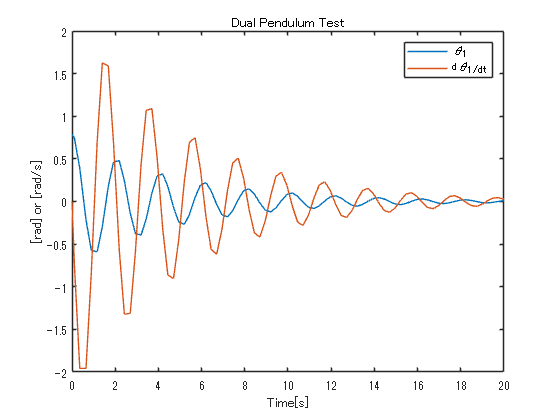


solveHandler = matlabFunction(V,'vars',{'t','Y'});

initCond = [pi/4 0];
TimeLentgh = [0 20];
sols = ode45(solveHandler,TimeLentgh,initCond);

%% 描画
plot(sols.x,sols.y)
legend('\theta_1', 'd\theta_1/dt')
title('Dual Pendulum Test')
xlabel('Time[s]')
ylabel('[rad] or [rad/s]')